# 非线性脉冲压缩仿真 - 充气空芯光纤系统

作者：智能助手 最后更新：2023-10-15 实现功能：模拟超短脉冲在充气空芯光纤中的非线性压缩过程

## 基础参数设置

clear; clc;
close all;

% 物理常数
c = 299792458;          % 光速 [m/s]
hbar = 1.0545718e-34;  % 约化普朗克常数

% 时间窗口参数
T_window = 20e-12;     % 时域窗口大小 [s]（增大窗口避免截断）
num_points = 2^14;     % 采样点数（保证分辨率）
dt = T_window/num_points; 
t = (-num_points/2:num_points/2-1)*dt; % 时间向量 [s]

% 空芯光纤参数
fiber_length = 2.0;       % 光纤长度 [m]
core_radius = 270e-6;     % 纤芯半径 [m]
gas_pressure = 1.5;       % 氦气气压 [atm]
n2_He = 0.4e-23;          % 氦气非线性折射率 [m²/W]

% 输入脉冲参数（Ti:Sapphire激光器）
lambda0 = 780e-9;         % 中心波长 [m]
input_energy = 4e-3;       % 脉冲能量 [J]
FWHM_in = 25e-15;         % 初始脉宽 [s]

## 生成初始脉冲

A0 = generate_input_pulse(t, 0, FWHM_in, lambda0, input_energy);

## 光纤传输参数计算

计算模场有效面积

A_eff = 0.48*pi*core_radius^2; % 有效面积公式(3-3)

% 计算非线性系数
gamma = (2*pi*n2_He*gas_pressure) / (lambda0*A_eff);

% 计算色散参数（氦气正常色散）
beta2 = 1.038e-6;   % GVD [s²/m] 来自图3-3
beta3 = 0;           % TOD [s³/m]（假设高阶色散可忽略）

## 分步傅里叶传输算法

dz = 0.005;          % 步长 [m] 
N_steps = round(fiber_length/dz);
A = A0;              % 初始化场

for n = 1:N_steps
    
    fprintf('>>进度 %d/%d\n',n,N_steps);

    % 梯度气压处理（示例为线性梯度）
    current_pressure = gas_pressure * n/N_steps;
    current_gamma = gamma * current_pressure/gas_pressure;
    
    % 非线性步：SPM + 自陡峭
    A = nonlinear_step(A, dz, current_gamma, dt, lambda0);
    
    % 色散步：GVD + 高阶色散
    A = dispersion_step(A, dz, beta2, beta3, dt);
    
    % 脉冲居中处理（防止偏移）
    [~,peak_idx] = max(abs(A).^2);
    A = circshift(A, -peak_idx + floor(num_points/2));
end

>>进度 1/400
>>进度 2/400
>>进度 3/400
>>进度 4/400
>>进度 5/400
>>进度 6/400
>>进度 7/400
>>进度 8/400
>>进度 9/400
>>进度 10/400
>>进度 11/400
>>进度 12/400
>>进度 13/400
>>进度 14/400
>>进度 15/400
>>进度 16/400
>>进度 17/400
>>进度 18/400
>>进度 19/400
>>进度 20/400
>>进度 21/400
>>进度 22/400
>>进度 23/400
>>进度 24/400
>>进度 25/400
>>进度 26/400
>>进度 27/400
>>进度 28/400
>>进度 29/400
>>进度 30/400
>>进度 31/400
>>进度 32/400
>>进度 33/400
>>进度 34/400
>>进度 35/400
>>进度 36/400
>>进度 37/400
>>进度 38/400
>>进度 39/400
>>进度 40/400
>>进度 41/400
>>进度 42/400
>>进度 43/400
>>进度 44/400
>>进度 45/400
>>进度 46/400
>>进度 47/400
>>进度 48/400
>>进度 49/400
>>进度 50/400
>>进度 51/400
>>进度 52/400
>>进度 53/400
>>进度 54/400
>>进度 55/400
>>进度 56/400
>>进度 57/400
>>进度 58/400
>>进度 59/400
>>进度 60/400
>>进度 61/400
>>进度 62/400
>>进度 63/400
>>进度 64/400
>>进度 65/400
>>进度 66/400
>>进度 67/400
>>进度 68/400
>>进度 69/400
>>进度 70/400
>>进度 71/400
>>进度 72/400
>>进度 73/400
>>进度 74/400
>>进度 75/400
>>进度 76/400
>>进度 77/400
>>进度 78/400
>>进度 79/400
>>进度 80/400
>>进度 81/400
>>进度 82/400
>>进度 83/400
>>进度 84/400
>

## 脉冲压缩（色散补偿）

寻找最佳GDD补偿量

GDD_comp = linspace(-3000e-30, 0, 100); % 扫描范围 [s²]
compressed_pulses = zeros(length(GDD_comp), num_points);

for k = 1:length(GDD_comp)
    compressed_pulses(k,:) = compress_pulse(A, GDD_comp(k), dt);
end

% 计算脉宽
pulse_widths = arrayfun(@(k) fwhm(t, abs(compressed_pulses(k,:)).^2), 1:length(GDD_comp));

% 找到最佳压缩点
[best_width, idx] = min(pulse_widths);
best_GDD = GDD_comp(idx);
A_compressed = compressed_pulses(idx,:);

## 结果可视化

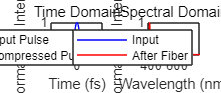

figure('Position',[100 100 1200 500])

% 原始与压缩脉冲对比
subplot(1,2,1)
plot(t*1e15, abs(A0).^2/max(abs(A0).^2), 'b')
hold on
plot(t*1e15, abs(A_compressed).^2/max(abs(A_compressed).^2), 'r')
xlim([-100 100])
xlabel('Time (fs)')
ylabel('Normalized Intensity')
legend('Input Pulse', 'Compressed Pulse')
title('Time Domain')

% 频谱展宽对比
subplot(1,2,2)
[~, spec_input] = calc_spectrum(A0, dt, lambda0);
[lambda_nm, spec_output] = calc_spectrum(A, dt, lambda0);
plot(lambda_nm, spec_input/max(spec_input), 'b')
hold on
plot(lambda_nm, spec_output/max(spec_output), 'r')
xlabel('Wavelength (nm)')
ylabel('Normalized Intensity')
legend('Input', 'After Fiber')
title('Spectral Domain')

## 关键函数定义

function A = generate_input_pulse(t, t0, FWHM, lambda0, energy)
    c = 299792458;
    w0 = 2*pi*c/lambda0;
    tau = FWHM/(2*sqrt(log(2)));
    E_field = sqrt(energy) * exp(-(t-t0).^2/(2*tau^2));
    A = E_field .* exp(1j*w0*t);
end

function A = nonlinear_step(A, dz, gamma, dt, lambda0)
    % 包含SPM和自陡峭效应
    c = 299792458;
    T = numel(A)*dt;
    omega = 2*pi*(-numel(A)/2:numel(A)/2-1)/T; 
    
    % 自陡峭项 (1/w0)*∂/∂t
    w0 = 2*pi*c/lambda0;
    ss_factor = 1/(1i*w0);
    
    % 分步非线性薛定谔方程
    A = A .* exp(1j*gamma*dz*abs(A).^2) .* ...
        exp(ss_factor * dz * gradient(abs(A).^2, dt));
end

function A = dispersion_step(A, dz, beta2, beta3, dt)
    % 频域色散算子
    N = length(A);
    omega = 2*pi*fftshift((-N/2:N/2-1)/N)/dt;
    
    D = -1i*(0.5*beta2*omega.^2 + (1/6)*beta3*omega.^3)*dz;
    A = ifft(fft(A).*exp(D));
end

function [lambda_nm, spectrum] = calc_spectrum(A, dt, lambda0)
    % 计算频谱
    c = 299792458;
    N = length(A);
    domega = 2*pi/(N*dt);
    omega = (-N/2:N/2-1)*domega;
    lambda_nm = 2*pi*c./(omega + 2*pi*c/lambda0)*1e9;
    
    spec = abs(fftshift(fft(A))).^2;
    spec = spec/max(spec);
    lambda_nm = lambda_nm(N/2:end); % 只显示正频率部分
    spectrum = spec(N/2:end);
end

function width = fwhm(x, y)
    % 改进的FWHM计算（带插值）
    y = y/max(y);
    half_max = 0.5;
    above = find(y >= half_max);
    
    if isempty(above) || numel(above)<2
        width = NaN;
        return
    end
    
    % 左边界插值
    idx1 = above(1);
    if idx1 > 1
        x1 = interp1(y(idx1-1:idx1), x(idx1-1:idx1), half_max);
    else
        x1 = x(idx1);
    end
    
    % 右边界插值
    idx2 = above(end);
    if idx2 < numel(x)
        x2 = interp1(y(idx2:idx2+1), x(idx2:idx2+1), half_max);
    else
        x2 = x(idx2);
    end
    
    width = x2 - x1;
end

function A_compressed = compress_pulse(A, GDD_comp, dt)
    % 色散补偿函数
    N = length(A);
    omega = 2*pi*fftshift((-N/2:N/2-1)/N)/dt;
    phase_comp = -0.5*GDD_comp*omega.^2;
    A_compressed = ifft(fft(A).*exp(1i*phase_comp));
end